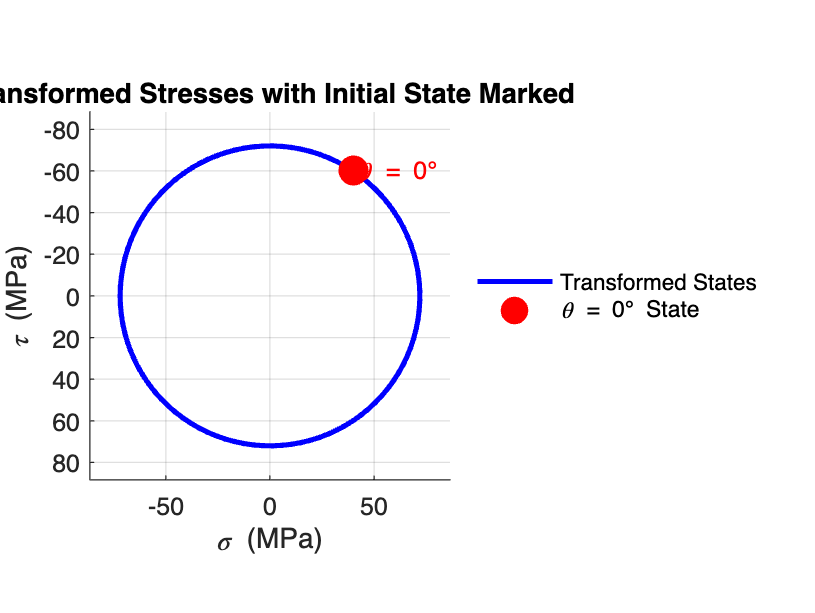

% Define stress components
sigma_x = 40;  % MPa
sigma_y = -40; % MPa
tau_xy = -60;  % MPa % Negative because positive tau is downward on positive face

% Create angle array for circle plotting (0 to 360 degrees)
n_samples = 100;
theta = linspace(0, 2*pi, n_samples);
sigma_x_theta = zeros(n_samples,1);
tau_xy_theta = zeros(n_samples,1);

% Loop through angles and calculate transformed stresses
for i = 1:n_samples
    [sigma_x_theta(i), tau_xy_theta(i)] = transform_stress_matrix(sigma_x, sigma_y, tau_xy, theta(i));
end

% Calculate initial point (θ=0)
[sigma_x_0, tau_xy_0] = transform_stress_matrix(sigma_x, sigma_y, tau_xy, 0);

% Create the plot
figure('Color', 'white');
hold on;
grid on;

% Plot transformed stress states
plot(sigma_x_theta, tau_xy_theta, 'b-', 'LineWidth', 2);

% Plot initial point (θ=0) with special marker
plot(sigma_x_0, tau_xy_0, 'ro', 'MarkerSize', 10, 'LineWidth', 2, 'MarkerFaceColor', 'r');

% Add text annotation for θ=0 point
text(sigma_x_0 + 2, tau_xy_0, '\theta = 0°', 'Color', 'r');

% Add labels and title
xlabel('\sigma (MPa)');
ylabel('\tau (MPa)');
title('Transformed Stresses with Initial State Marked');

% Add legend
legend_obj = legend('Transformed States', '\theta = 0° State');
set(legend_obj, 'Location', 'eastoutside');
set(legend_obj, 'EdgeColor', 'none');
set(legend_obj, 'Color', [1 1 1 0.8]);

% Make the plot square and set axis limits
max_val = max(max(abs(sigma_x_theta)), max(abs(tau_xy_theta))) * 1.2;
axis([-max_val max_val -max_val max_val]);
axis equal;

% Flip the y-axis to point downward
set(gca, 'YDir', 'reverse');

% Add grid
grid on;


% Display numerical results for initial state
fprintf('\nInitial State (θ = 0°):\n');


Initial State (θ = 0°):


fprintf('σx = %.2f MPa\n', sigma_x_0);

σx = 40.00 MPa


fprintf('τxy = %.2f MPa\n', tau_xy_0);

τxy = -60.00 MPa



% Function definitions must be at the end of the file

function [sigma_x_theta, tau_xy_theta] = transform_stress_matrix(sigma_x, sigma_y, tau_xy, theta)
    % Form the transformation matrix R(2θ)
    R = [cos(2*theta), sin(2*theta);
         -sin(2*theta), cos(2*theta)];
    
    % Form the stress difference vector
    stress_diff = [(sigma_x - sigma_y)/2;
                   tau_xy];
    
    % Perform matrix multiplication
    result = R * stress_diff;
    
    % Calculate transformed stresses
    sigma_x_theta = result(1) + (sigma_x + sigma_y)/2;
    tau_xy_theta = result(2);
end